 clear
 clc

%Set Values
ChordD = struct2array(load('ChordD.mat'));
TwistA = struct2array(load('TwistA.mat'));
 FreeNormVel = 10; % The velocity of wind tunnel (m/s)
 N = 2; % Number Of fans
 row = 1.204;
 kVisc = 1.506e-5;
 Diameter = 0.5;
 slices = 100;
 Mach = 30/343;
 Ncrit = 5;
 aopt = 1/3;
 RootStart = 0.035;
 adashopt = 0.02;
  Constant = (1/2)*row*pi*((Diameter/2)^2)*(10^3)

Constant = 118.2024

 
 ReInit = [59000,57000]

ReInit =        59000       57000


 AirfoilChangeR = Diameter/8; %Turn into an array if more than one change

 % for i = 1:(length(AirfoilChangeR)+1)
 %      [XFOILA1,DesAlpha(i)] = run_xfoil(SG60(:,((i*2)-1):(i*2)), ReInit(i), Mach, Ncrit, min(alpha_grid), max(alpha_grid)); %Idk why warning it seems to work 
 %  %Calculated from XFOIL data
 %   ForTwstGrphAlpha = DesAlpha;
 %  [~,idx] = min(abs(XFOILA1(:,1)-DesAlpha(i)));
 %  LiftCoef(i) = XFOILA1(idx,2);
 %  end

% ONLY RUN THIS ONCE

 % Sample airfoil coordinates (x, y)
SG60(:,1:2) = table2array(readtable('SG6040cords.csv','PreserveVariableNames',true));
SG60(:,3:4) = table2array(readtable('SG6043cords.csv','PreserveVariableNames',true));

% Example ranges
Re_grid = logspace(4.3, 5.05, 10);        % 10 values 
alpha_grid = linspace(-10, 25, 31);  % -10 to 20 degrees
DesAlpha_table = zeros((length(AirfoilChangeR)+1), length(Re_grid));
for i = 1:(length(AirfoilChangeR)+1)
     [XFOILA1,DesAlpha(i)] = run_xfoil(SG60(:,((i*2)-1):(i*2)), ReInit(i), Mach, Ncrit, min(alpha_grid), max(alpha_grid)); %Idk why warning it seems to work 
 %Calculated from XFOIL data
 ForTwstGrphAlpha = DesAlpha;
 [~,idx] = min(abs(XFOILA1(:,1)-DesAlpha(i)));
 LiftCoef(i) = XFOILA1(idx,2);
    for j = 1:length(Re_grid)
        [XFOIL, ~] = run_xfoil(SG60(:,((i*2)-1):(i*2)), Re_grid(j), Mach, Ncrit, min(alpha_grid), max(alpha_grid));
        % XFOIL(:,1) = alpha, XFOIL(:,2) = CL, XFOIL(:,3) = CD
        CL = XFOIL(:,2);
        CD = XFOIL(:,3);
        CLCD = CL ./ CD;
        [~, idx_max] = max(CLCD);
        DesAlpha_table(i, j) = XFOIL(idx_max, 1); % Store optimum alpha for this Re
        % (Also fill CL_table and CD_table as before)
        for k = 1:length(alpha_grid)
            idx = find(abs(XFOIL(:,1)-alpha_grid(k)) == min(abs(XFOIL(:,1)-alpha_grid(k))), 1);
            CL_table(i,j,k) = XFOIL(idx,2);
            CD_table(i,j,k) = XFOIL(idx,3);
        end
    end
end

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

[XFOILComparison43, ~] = run_xfoil(SG60(:,1:2), 50000, Mach, Ncrit, -5, 35);

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

[XFOILComparison40, ~] = run_xfoil(SG60(:,3:4), 50000, Mach, Ncrit, -5, 35);

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

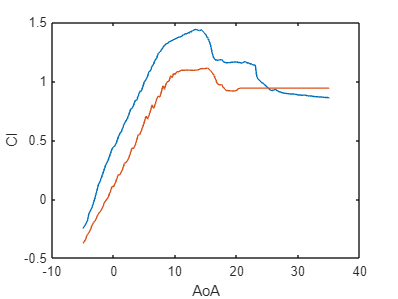

figure
plot(XFOILComparison40(:,1),XFOILComparison40(:,2))
hold on
plot(XFOILComparison43(:,1),XFOILComparison43(:,2))
hold off
xlabel('AoA')
ylabel('Cl')

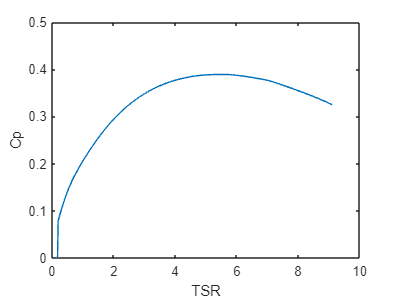

%Using slides (lubbock) method] (Only uses sg43 airfoil rn)
%Seems to scale wierdly with lambda
Wlist=zeros(91,slices); %added this (lothaire)
philist = zeros(91, slices); %added this (lothaire) just to store values
storePw = zeros(1,91);
storea = zeros(91,slices);
storealpha = zeros(91,slices);
for ratiolambda = 0.1:0.1:9.1
    alist = [];
    alphalist = [];
    ReList = [];
angvel = (ratiolambda*FreeNormVel)/(Diameter/2);
fn=0;
Pw = 0;
Torque = 0;
Wtot = 0;
TwistEquation = @(R,DesAlph) (atand(Diameter./(3.55*(R).^1.06*ratiolambda))-DesAlph); 
ChordEquation = @(R,LiftC) (((16*pi*R)/(N*LiftC)).*sin((1/3)*atan(Diameter./(2*R*ratiolambda))).^2);
for R = linspace(RootStart,(Diameter/2),slices)
i = find(R <= AirfoilChangeR, 1); if isempty(i), i = length(AirfoilChangeR)+1; end
a = aopt;
adash = adashopt;
phi = (atand((1-a)*Diameter/(2*ratiolambda*R*(1+adash))));
phi1 = phi + 10; 
brnum = 0 ;
while abs(phi - phi1) > 0.001
    brnum = brnum+1;
Alpha = (-(TwistEquation(R,DesAlpha(i)) - phi));
W = sqrt(((angvel*R)^2)+(FreeNormVel*(1-a))^2);
Re(i) = ((W*ChordEquation(R,LiftCoef(i)))/kVisc);
% DesAlpha(i) = interp1(Re_grid, DesAlpha_table(i,:), Re(i), 'linear', 'extrap');

% Extract the 2D slices from CL_table and CD_table
cl_slice = squeeze(CL_table(i,:,:));
cd_slice = squeeze(CD_table(i,:,:));

% Transpose if needed to match grid dimensions
if size(cl_slice,1) ~= length(alpha_grid)
    cl_slice = cl_slice.';
    cd_slice = cd_slice.';
end

% Create interpolants with extrapolation
liftInterp = griddedInterpolant({alpha_grid, Re_grid}, cl_slice, 'linear', 'linear');
dragInterp = griddedInterpolant({alpha_grid, Re_grid}, cd_slice, 'linear', 'linear');

% Interpolate lift and drag coefficients
LiftCoef(length(AirfoilChangeR)+2) = liftInterp(Alpha, Re(i));
DragCoef(length(AirfoilChangeR)+2) = dragInterp(Alpha, Re(i));

% to use the stall correction function, we would probably also need an
% array of Cd0 and AOA0 for the arifoils, these are the final two inputs in the equation
% [LiftCoef(length(AirfoilChangeR)+2),DragCoef(length(AirfoilChangeR)+2)] =
% stall_corrected(XFOIL(idx2,(2+3*(i-1))),XFOIL(idx2,(3+3*(i-1))),Alpha,(R/(Diameter/2)),ChordEquation(R,LiftCoef(i)),angvel,0.04125,-1); 
a = ratiolambda*(LiftCoef(length(AirfoilChangeR)+2)*N*ChordEquation(R,LiftCoef(i)))/(Diameter*pi*4*sind(phi));
adash = 1/(((2*pi*4*sind(phi)*cosd(phi))/(LiftCoef(length(AirfoilChangeR)+2)*N*ChordEquation(R,LiftCoef(i))))-1);
phi1 = phi;
phi = (atand((1-a)*Diameter/(2*ratiolambda*R*(1+adash))));
if brnum == 10
    break
end
end
alphalist = [alphalist,Alpha];
alist = [alist,a];
W = sqrt(((angvel*R)^2)+(FreeNormVel*(1-a))^2);
ReList = [ReList,((W*ChordEquation(R,LiftCoef(i)))/kVisc)];
% Wlist(round((ratiolambda-1)/0.1)+1, round((R - RootStart)/((Diameter/2 - RootStart)/(slices-1))) + 1) = W; %added this (lothaire) just to store values
% philist(round((ratiolambda-1)/0.1)+1, round((R - RootStart)/((Diameter/2 - RootStart)/(slices-1))) + 1) = phi; %added this (lothaire) just to store values
Wtot = Wtot+W;
Ftip = (2/pi)*acos(exp(-(N/2)*(((Diameter/2)-R)/(R*sind(phi))))); %Prandtls tip loss
Froot = (2/pi)*acos(exp(-(N/2)*((R-(RootStart))/(R*sind(phi))))); %Prandtls root loss
Ftotal = Ftip*Froot; %total tip and root corrections
dR = ((Diameter/2)-(RootStart))/slices;
ForceTot = N * 0.5 * row * W^2 * ChordEquation(R,LiftCoef(i)) * (LiftCoef(length(AirfoilChangeR)+2)*sind(phi)-DragCoef(length(AirfoilChangeR)+2)*cosd(phi));
dPw = (ForceTot * R - 0.03) * angvel * dR; %0.03 accounts for motor resistance
Pw = Pw + dPw*Ftotal;
Torque = Torque + (ForceTot * R - 0.03) * dR*Ftotal;

end
storePw(int32(ratiolambda*10)) = Pw;
storeTorque(int32(ratiolambda*10)) = Torque;
storea(int32(ratiolambda*10),:) = alist;
storealpha(int32(ratiolambda*10),:) = alphalist;
storeRe(int32(ratiolambda*10),:) = ReList;
StoreW(int32(ratiolambda*10)) = Wtot/slices;
end
[val, optlambda] = max(storePw);
plot(0.1:0.1:9.1,storePw/Constant)
xlabel('TSR')
ylabel('Cp')
ylim([0,0.5])

Power = val

Power = 45.9697

storeRe(optlambda,:)

ans = 1.0e+04 *

    5.7846    5.9162    6.0425    6.1606    6.2709    6.3748    6.4726    6.5645    6.6521    6.7354    6.8137    6.8874    6.9567    5.6742    5.7235    5.7707    5.8151    5.8569    5.8964    5.9336    5.9687    6.0019    6.0333    6.0630    6.0912    6.1178    6.1430    6.1670    6.1897    6.2113    6.2319    6.2514    6.2700    6.2877    6.3045    6.3206    6.3360    6.3507    6.3647    6.3781    6.3909    6.4031    6.4149    6.4261    6.4369    6.4472    6.4571    6.4666    6.4757    6.4845


mean(storeRe(optlambda,1:37))

ans = 6.1971e+04

mean(storeRe(optlambda,38:end))

ans = 6.5754e+04

storealpha(optlambda,:)

ans =    11.0069   10.7895   10.6007   10.4110   10.2168   10.0318    9.8555    9.6840    9.5373    9.4097    9.2883    9.1730    9.0647    8.5255    8.4334    8.3611    8.2935    8.2288    8.1690    8.1120    8.0585    8.0074    7.9611    7.9171    7.8753    7.8357    7.7983    7.7629    7.7309    7.7000    7.6709    7.6435    7.6176    7.5932    7.5702    7.5494    7.5302    7.5122    7.4952    7.4792    7.4642    7.4500    7.4366    7.4241    7.4123    7.4012    7.3907    7.3808    7.3714    7.3622


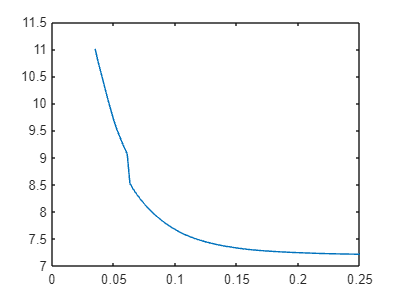

% storea(optlambda,:) %Array of a at optimum TSR
% StoreW(optlambda) %AvgVelociity
plot(linspace(RootStart,Diameter/2,slices),storealpha(optlambda,:))

optlambda = (optlambda)/10

optlambda = 5.5000

StartingTorque = storeTorque(2)

StartingTorque = 1.1672


%Could maybe optimise the following to allow varying of splits and airfoils etc
r(2,:) = (Diameter/8):0.001:(Diameter/2);
r(1,:) = NaN;
Rt2Chnge = (RootStart):0.001:(Diameter/8);
r(1,1:length(Rt2Chnge)) = Rt2Chnge;

% % NEW METHOD
figure
ChordEquation = @(R,LiftC) (((16*pi*R)/(N*LiftC)).*sin((1/3)*atan(Diameter./(2*R*optlambda))).^2);
for i = 1:2
plot(r(i,:),ChordEquation(r(i,:),LiftCoef(i)))
hold on
end
Chord(1,:) = [r(1,1:length(Rt2Chnge)),r(2,:)];
Chord(2,:)= [ChordEquation(r(1,1:length(Rt2Chnge)),LiftCoef(1)),ChordEquation(r(2,:), LiftCoef(2))]

Chord =     0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590    0.0600    0.0610    0.0620    0.0625    0.0635    0.0645    0.0655    0.0665    0.0675    0.0685    0.0695    0.0705    0.0715    0.0725    0.0735    0.0745    0.0755    0.0765    0.0775    0.0785    0.0795    0.0805    0.0815    0.0825    0.0835
    0.0779    0.0778    0.0776    0.0774    0.0772    0.0769    0.0766    0.0762    0.0759    0.0755    0.0751    0.0747    0.0742    0.0737    0.0733    0.0728    0.0723    0.0718    0.0713    0.0708    0.0702    0.0697    0.0692    0.0687    0.0681    0.0676    0.0671    0.0665    0.0534    0.0530    0.0525    0.0521    0.0517    0.0513    0.0508    0.0504    0.0500    0.0496    0.0492    0.0488    0.0484    0.0480    0.0476    0.0472    0.0468    0.0464    0.0460    0.0457    0.0453 

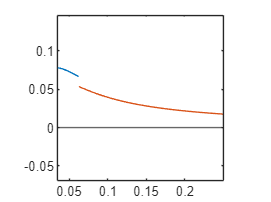

% MeanChord = mean([ChordEquation(r(2,:)),ChordEquation(r(1,1:length(Rt2Chnge)))])
yline(0)
set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1],'XLim',[RootStart,(Diameter/2)])
hold off


% To find twist
figure
TwistEquation = @(R,DesAlph) (atand(Diameter./(3.55*(R.^1.06)*5.5))-DesAlph);  
for i = 1:2
plot(r(i,:),TwistEquation(r(i,:),ForTwstGrphAlpha(i)))
hold on
end
Twist(1,:) = [r(1,1:length(Rt2Chnge)),r(2,:)];
Twist(2,:) = [TwistEquation(r(1,1:length(Rt2Chnge)),ForTwstGrphAlpha(1)),TwistEquation(r(2,:),ForTwstGrphAlpha(2))]

Twist =     0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590    0.0600    0.0610    0.0620    0.0625    0.0635    0.0645    0.0655    0.0665    0.0675    0.0685    0.0695    0.0705    0.0715    0.0725    0.0735    0.0745    0.0755    0.0765    0.0775    0.0785    0.0795    0.0805    0.0815    0.0825    0.0835
   34.0683   33.2196   32.3976   31.6014   30.8301   30.0828   29.3587   28.6571   27.9770   27.3177   26.6786   26.0587   25.4575   24.8742   24.3082   23.7589   23.2256   22.7077   22.2047   21.7161   21.2412   20.7796   20.3309   19.8945   19.4699   19.0569   18.6549   18.2636   18.8218   18.4458   18.0796   17.7227   17.3750   17.0360   16.7055   16.3831   16.0687   15.7619   15.4625   15.1703   14.8849   14.6063   14.3341   14.0681   13.8083   13.5542   13.3059   13.0631   12.8256 

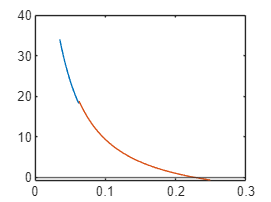

yline(0)
hold off

% % LUBBOCK METHOD
% % To find chord distribution
% AreaBlade = (((Diameter/2)^2)/(N*ratiolambda))
% ChordIntegral = @(k) (integral(@(x) (k./x),(Diameter/20),(Diameter/2))-AreaBlade)
% k = fzero(ChordIntegral,0.1)
% ChordEquation = @(R) (k./R)
% plot(r,ChordEquation(r))
% yline(0)
% set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1],'XLim',[Diameter/20,(Diameter/2)])
% hold off

% % To find twist
% figure
% for i = 1:2
% TwistEquation = @(R) (atand(Diameter./(3*R*ratiolambda))-DesAlpha(i));
% plot(r(i,:),TwistEquation(r(i,:)))
% hold on
% end
% yline(0)
% hold off

% FOR WHATEVER REASON THIS CODE USING I2A IS WRONG (IDK WHY)
% boundr(1:2) = [(Diameter/2),(Diameter/20)];
% for i = 1:2
% ChordEquation = @(R) (((16*pi*R)/(N*LiftCoef(i))).*sin((1/3)*atan(Diameter./(2*R*ratiolambda))).^2); %try to remove later for ease of code
% Fn(i) = 0; %Found iteratively, Loop till convergence
%  Fn1(i) = 10;
% while abs(Fn(i) - Fn1(i)) > 0.00001
%  angvel = (ratiolambda*FreeNormVel)/(Diameter/2);
%  NormVel = (FreeNormVel/2) - (1/2)*sqrt((FreeNormVel^2) + (8*Fn(i))/(row*pi*Diameter^2)); %the second part applies the induced stuff
%  TangVel = @(x) (angvel*x); %func of R
%  TotalVel =  @(x) (sqrt((x.^2)+NormVel^2)); %func of TangVel
%  dAOA =  @(x) (atand(NormVel./x)); %func of TangVel
% 
%  SingleIntegral = @(a,b,c) (1/2*row*(a.^2).*c.*(LiftCoef(i)*cosd(b)+(sind(b)*DragCoef(i))));
%  Fn1(i) = Fn(i);
%  Fn(i) = (N)*integral(@(x) SingleIntegral(TotalVel(TangVel(x)),dAOA(TangVel(x)),ChordEquation(x)),(Diameter/8),boundr(i));
% end
% SingleIntegralp = @(a,b,c) (1/2*row*(a.^2).*c.*(DragCoef(i)*cosd(b)-(sind(b)*LiftCoef(i))));
% Pw(i) = (N)*angvel*integral(@(x) SingleIntegralp(TotalVel(TangVel(x)),dAOA(TangVel(x)),ChordEquation(x).*x),(Diameter/8),boundr(i));
% end
% Fn =  Fn(1) - Fn(2)
% Pw = Pw(1) - Pw(2)

function [Cl,Cd] = stall_corrected(xfoil_cl,xfoil_cd,Alpha,r_ratio,c,angvel,Cd0,AoA0) %function to apply stall correction
    if r_ratio>0.3 && r_ratio<0.95 %from a paper, how the shift value varies along the blade
        % these equations are from the 1998 AIAA paper
        clp = 2*pi*(Alpha-AoA0);
        cr_ratio = c/(r_ratio*(0.245)); %this has the radius in it, in case that changes in the future
        big_lamb = ((angvel)*0.245)/sqrt(100 + ((angvel)*0.245)^2);
        fl = ( (1.6*cr_ratio/0.1267) * ( (1-cr_ratio^(1/(big_lamb*r_ratio)) ) / (1+cr_ratio^(1/(big_lamb*r_ratio))) )-1) / (2*pi); 
        fd = ( (1.6*cr_ratio/0.1267) * ( (1-cr_ratio^(1/(2*big_lamb*r_ratio)) ) / (1+cr_ratio^(1/(2*big_lamb*r_ratio))) )-1) / (2*pi); 
        del_cl =fl*(clp-xfoil_cl);
        del_cd =fd*(xfoil_cd-Cd0);
        Cl = xfoil_cl+del_cl;
        Cd = xfoil_cd-del_cd;
    else
        Cl = xfoil_cl;
        Cd = xfoil_cd;
    end
end